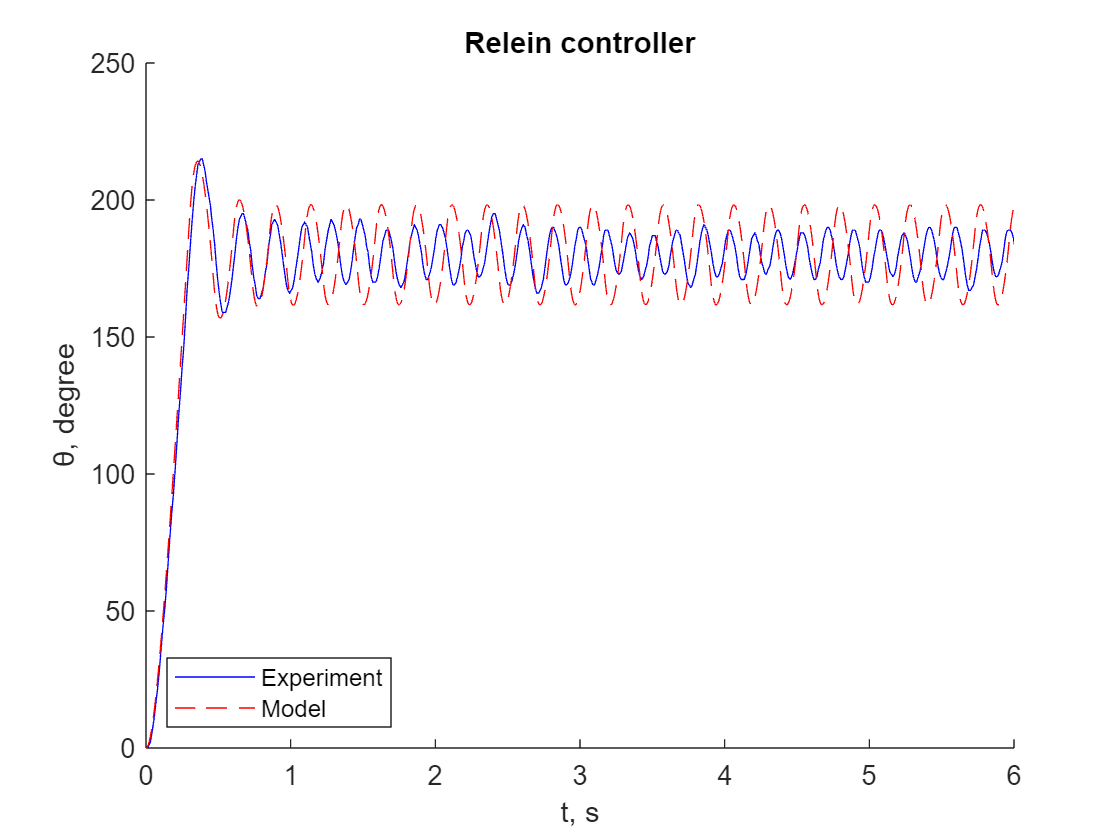

ke = 0.4987;
km = ke;
Tm = 0.0886;  
R =  8.8696;
L = 0.0047;
J = 0.0023;
target = 180;
Umin = 8.05;
M = 0.02; 

data1=readmatrix('rele_reg_15n2.txt');
X1=data1(:,1);
Y1=data1(:,2);

simout=sim('R_model.slx');

xlim([0 6])

hold on
plot(X1,Y1,'b')
plot(simout.simulinkR(:,1),simout.simulinkR(:,2),'r--')

title('Relein controller')
xlabel("t, s")
ylabel('θ, degree')
legend('Experiment', 'Model','Location','southwest')